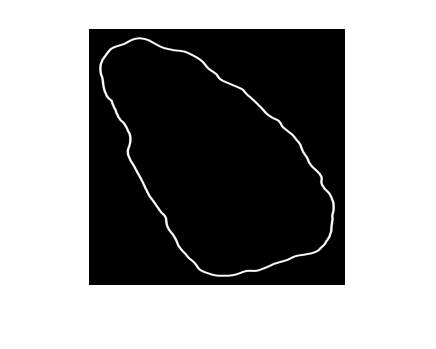

img = imread("dSq2j.jpg");
img = imresize(img, [256, 256]);
% img = im2gray(img);
imshow(img);

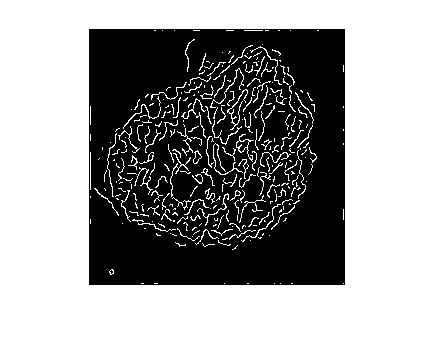

% Get edges 
edgeimg = edge(img, "canny", 0.2);
imshow(edgeimg);

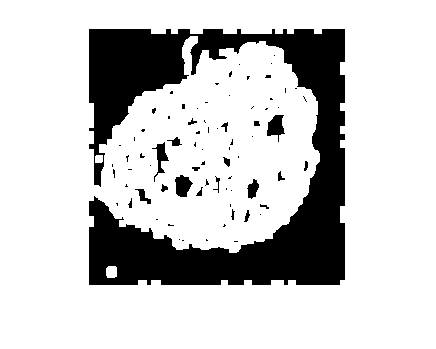

imshow(imdilate(edgeimg, strel('disk', 4, 8)));

edgeimg = imdilate(edgeimg, strel('disk', 4, 8));

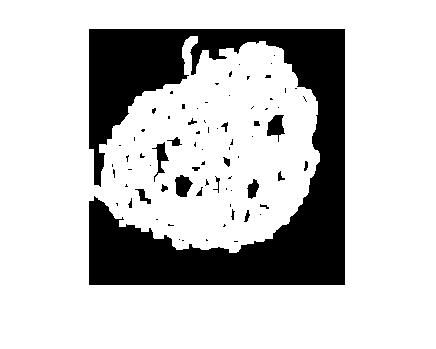

% Create boundaries for img
imshow(bwareafilt(edgeimg, 1));

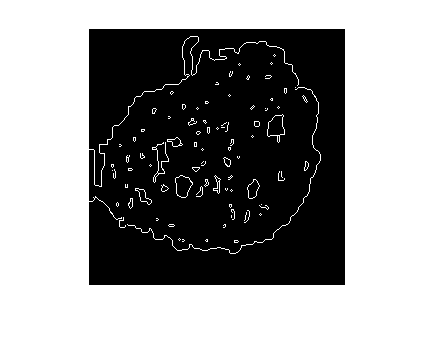

edgeimg = bwareafilt(edgeimg, 1);
imshow(edge(edgeimg));

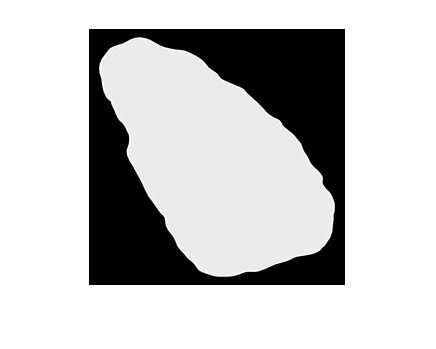

% fill the image
% holes = 
img = imfill(img, "holes");
imshow(img);

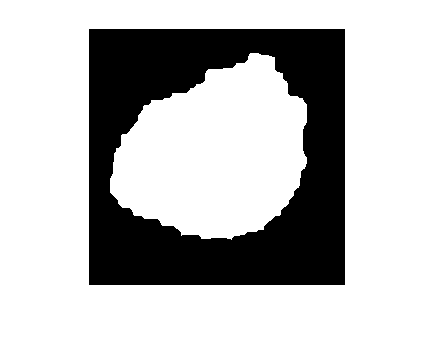

newimg = imerode(img, strel('disk', 10, 8));
imshow(newimg)

% run for loop and erode img
newimg = img;
for i=1:45      
    newimg = imerode(newimg, strel('disk', 2, 4));
    imwrite(newimg, sprintf("c1/c1_dec_%03d.png", i));
end

% run for loop and dialate img
for i=1:40
    newimg = imdilate(newimg, strel('disk', 2, 8));
    imwrite(newimg, sprintf("c1/c1_inc_%03d.png", i));
end